% Simlulink
clear all; close all

m=0.0085;
g=9.81;
R1=47*1000

R1 = 47000

R2=1*1000

R2 = 1000

Rs=0.1

Rs = 0.1000


Kamp=R2/(R1+R2)/Rs %gain  

Kamp = 0.2083

v_bias=2.4 %volts

v_bias = 2.4000

I_bar=Kamp*v_bias %Amp

I_bar = 0.5000

x_bar=3.175*10^-3 %m

x_bar = 0.0032


C=m*g*(x_bar/I_bar)^2 %constant

C = 3.3623e-06

K_sensor=1.15590*10^3 %% (V/m) Slope of the linear region in your graph

K_sensor = 1.1559e+03

Num=-C/m*(2*I_bar/x_bar^2) %Numerator of the transfer funtion

Num = -39.2400

Den=2*C/m*I_bar^2/x_bar^3  %Denominator 

Den = 6.1795e+03



sensor_gain = 1155.90;
actuator_gain = 0.20833;

s=tf('s')

s =
 
  s
 
Continuous-time transfer function.



G=Num/(s^2-Den)

G =
 
    -39.24
  ----------
  s^2 - 6180
 
Continuous-time transfer function.



H=K_sensor*s^0

H =
 
  1156
 
Static gain.



V_hat=0.0;
V=x_bar*K_sensor

V = 3.6700

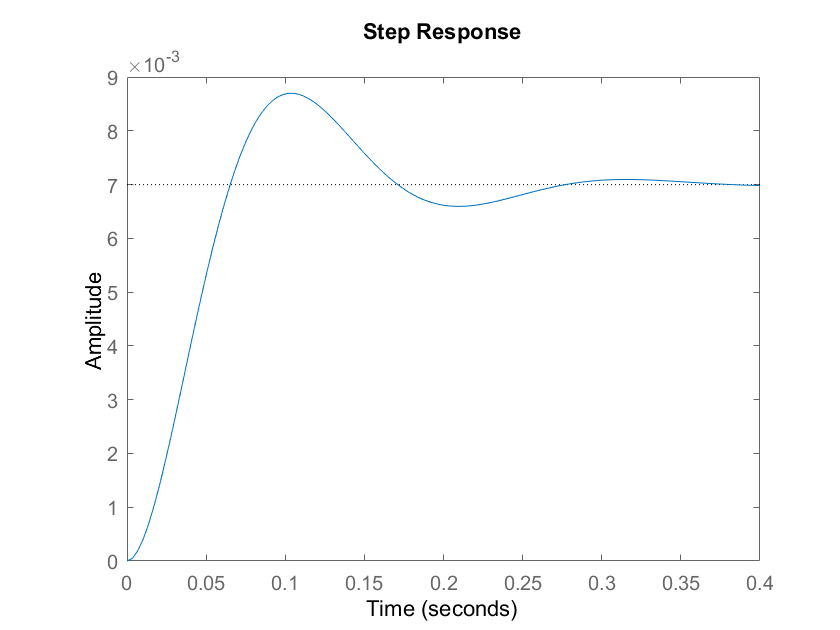

% SISO tool
K = -1.1194;
z = 100;
p = 150;
G_s = tf([-39.24*0.20833],[1 0 -6180]);
H_s = tf([1155.90]);
C_s = tf(K*[1 z],[1 p]);
closed = feedback(G_s*C_s,H_s);

figure(1);box on;
step(closed)
xlim([0,0.4])

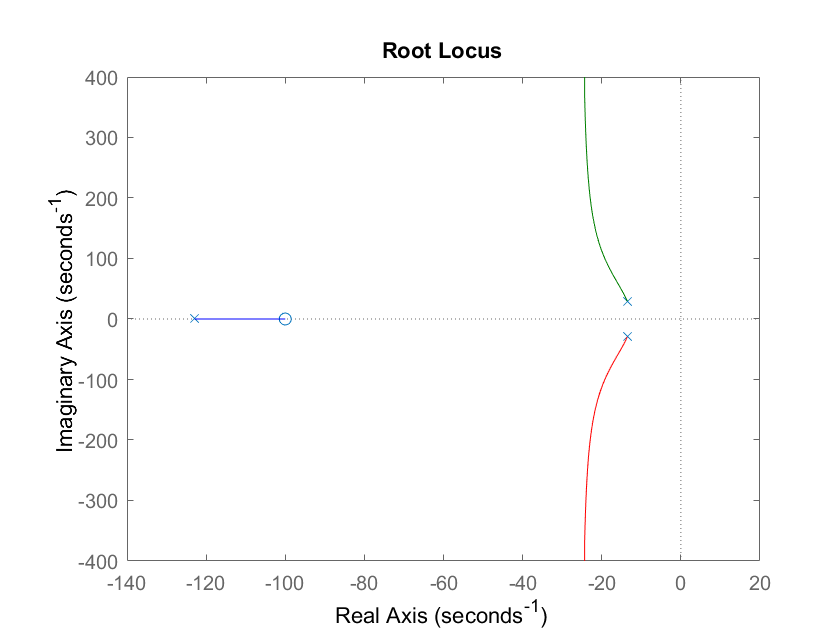


rlocus(closed)


allmargin(closed)

ans = struct with fields:
     GainMargin: Inf
    GMFrequency: Inf
    PhaseMargin: [1×0 double]
    PMFrequency: [1×0 double]
    DelayMargin: [1×0 double]
    DMFrequency: [1×0 double]
         Stable: 1
